# Final Project

(Any Warhol)

Written by Erin O'Neil

clear;clc;close all;

Code:

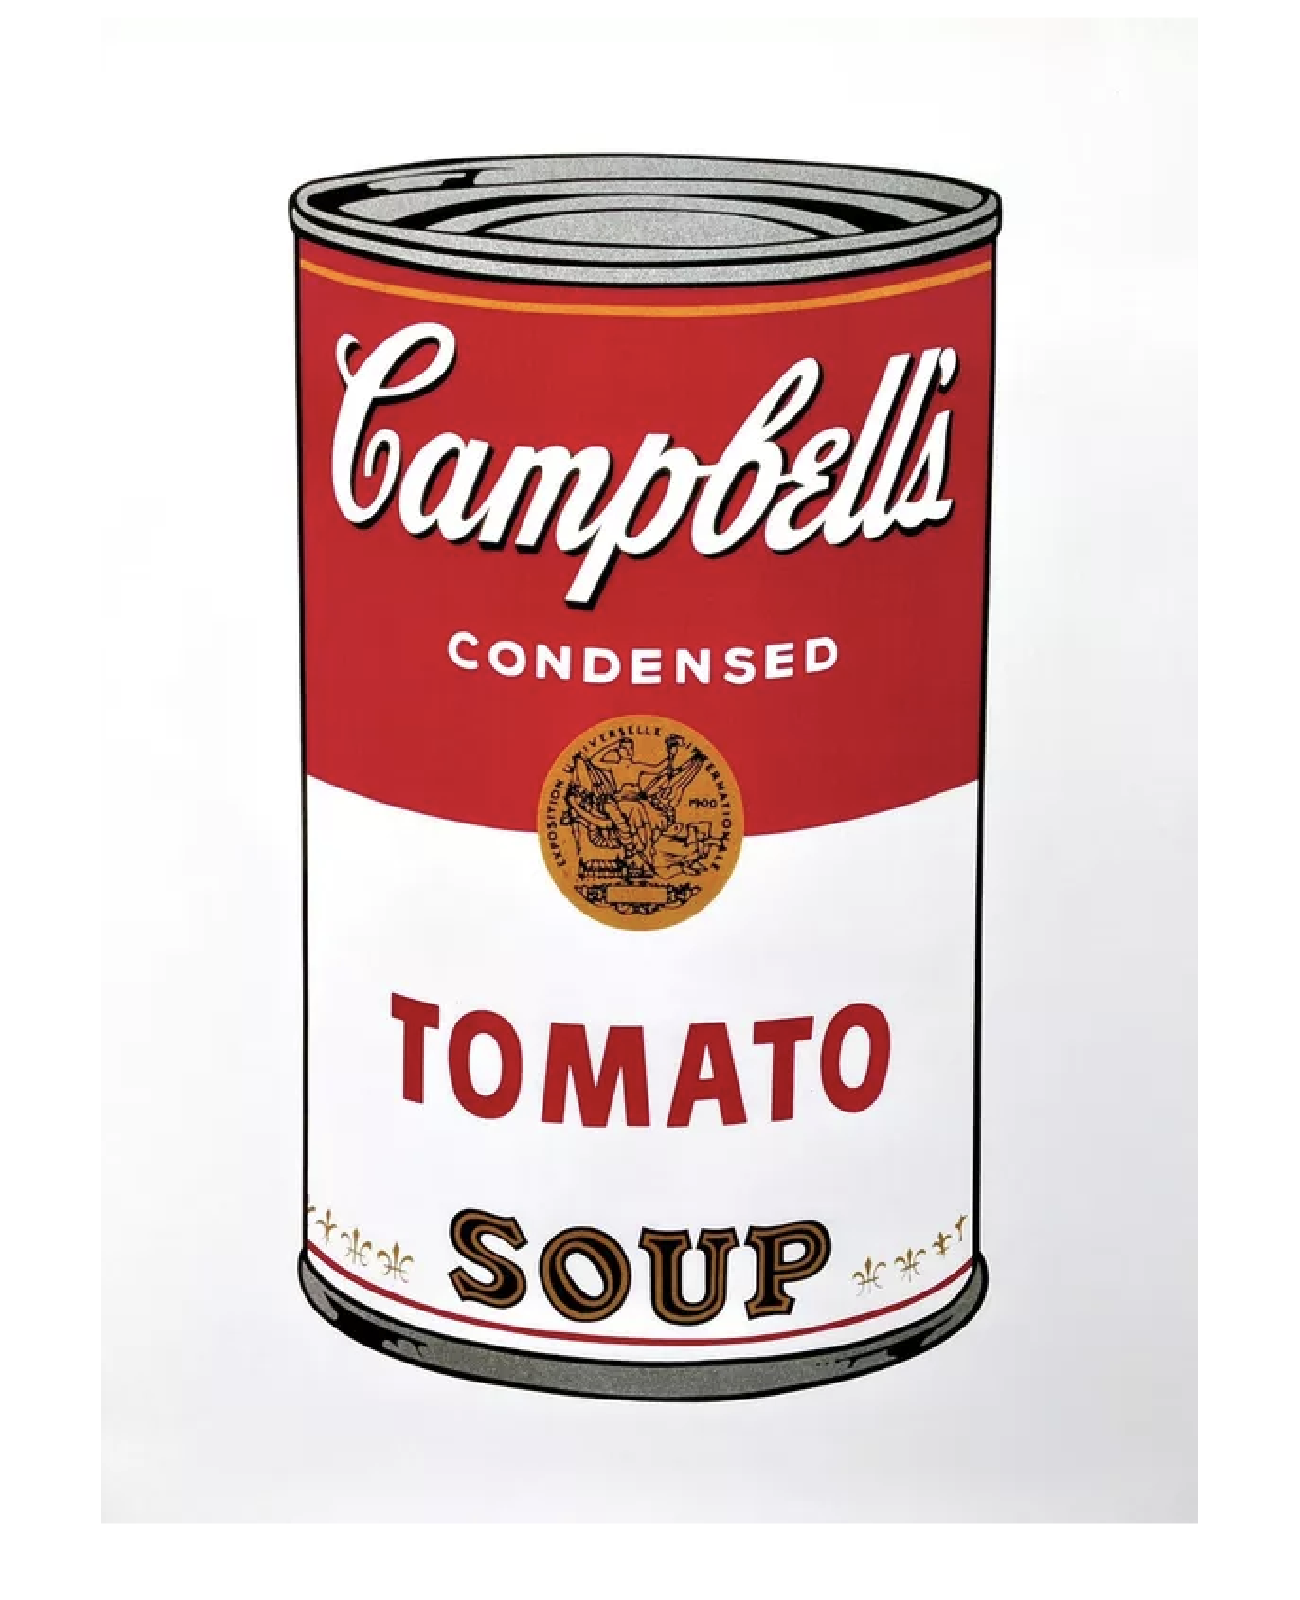

original = imread("soup.png");
imshow(original)

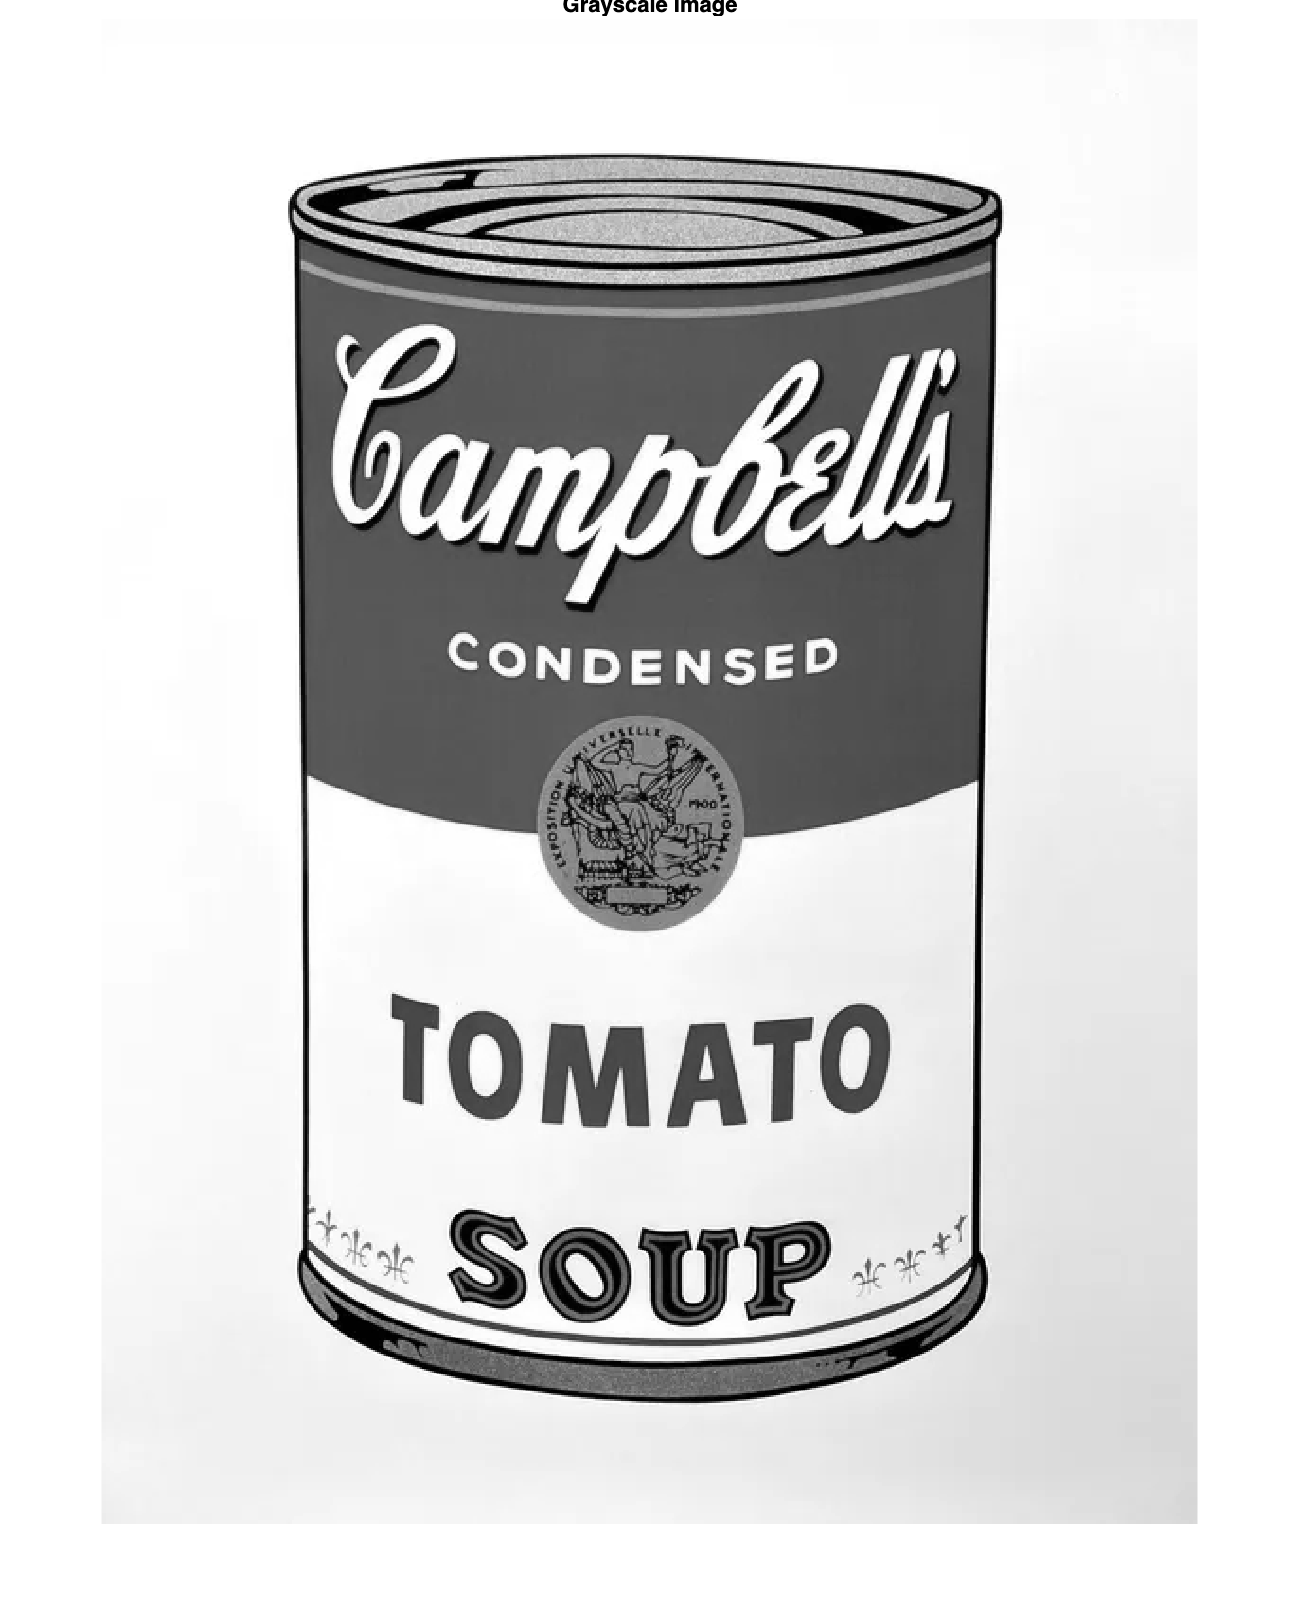



%%%%%%%%%%%%%% change image1 %%%%%%%%%%%%%%%%%%%%%%%
I1 = rgb2gray(original);

imshow(I1)
title("Grayscale Image")

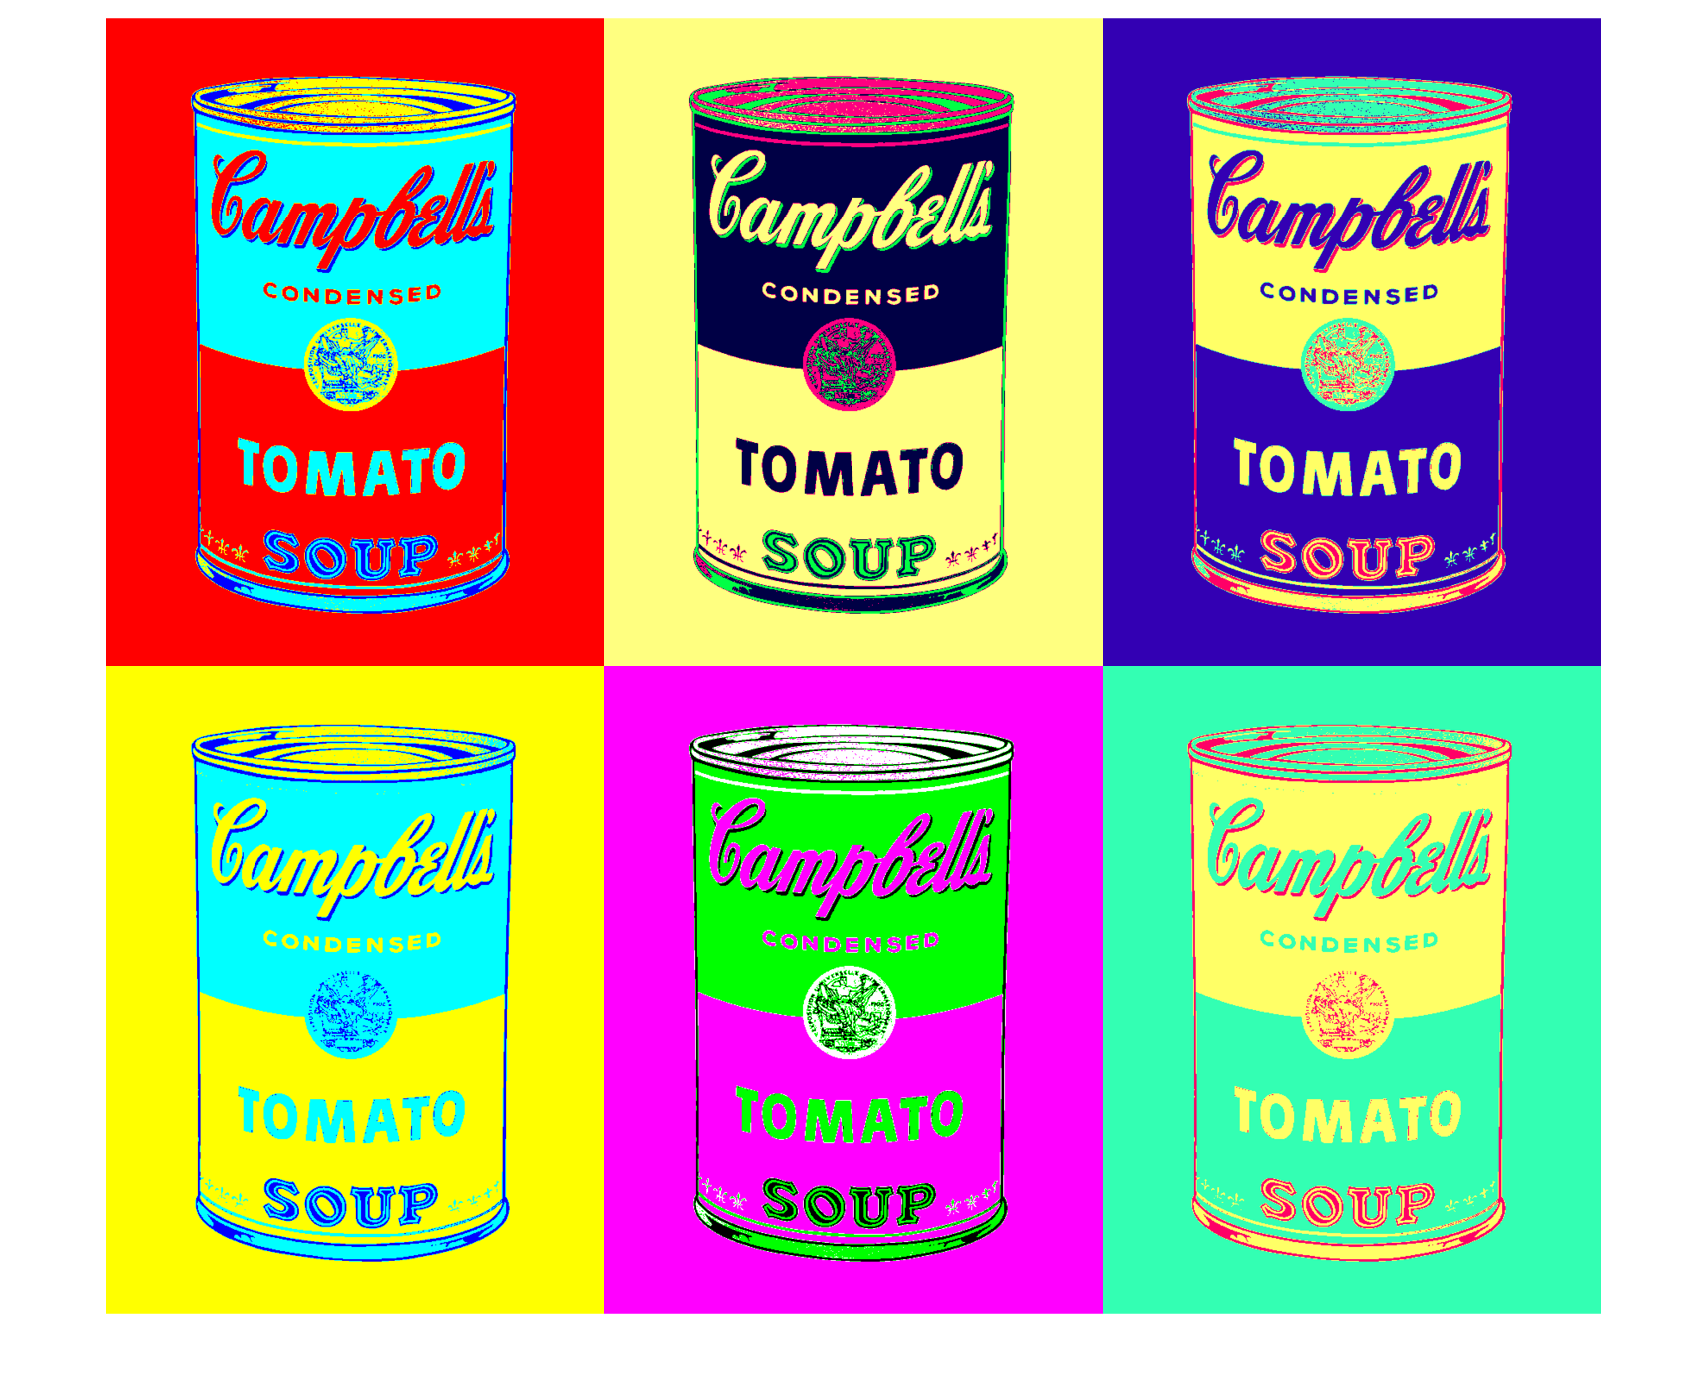


%threshold the image into k number of section
threshold = multithresh(I1,3);
labels = imquantize(I1,threshold); %imquantize(A,levels) quantizes image A using specified quantization values contained in the N element vector levels. Output image quant_A is the same size as A and contains N + 1 discrete integer values in the range 1 to N + 1 
colorsRGB = label2rgb(labels);

I1 = colorsRGB;




%%%%%%%%%%%%% change image2 %%%%%%%%%%%%%%%%%%%%%%%
I2 = rgb2gray(original);

%threshold the image into k number of section
threshold = multithresh(I2,3);
labels = imquantize(I2,threshold);
colorsRGB = label2rgb(labels);

imgEnhanced2 = imadjust(colorsRGB,[0.13 0.00 0.30; 0.75 1.00 1.00],[0.00 1.00 0.50; 1.00 0.00 0.27], [5.90 0.80 4.10]);
%imgEnhanced2 = imadjust(original,[0.20 0.00 0.09; 0.83 1.00 0.52],[0.00 0.00 1.00; 1.00 1.00 0.00], [1.10 2.70 1.00]);
I2 = imgEnhanced2;





%%%%%%%%%%%%%%% change image3 %%%%%%%%%%%%%%%%%%%%%
I3 = rgb2gray(original);

%threshold the image into k number of section
threshold = multithresh(I3,3);
labels = imquantize(I3,threshold);
colorsRGB = label2rgb(labels);

imgEnhanced3 = imadjust(colorsRGB,[0.00 0.00 0.00; 1.00 0.38 0.40],[1.00 0.00 0.70; 0.20 1.00 0.40], [4.90 4.00 1.70]);
I3 = imgEnhanced3;



%%%%%%%%%%%%%% change image4 %%%%%%%%%%%%%%%%%%%%%%%
I4 = rgb2gray(original);

%threshold the image into k number of section
threshold = multithresh(I4,3);
labels = imquantize(I4,threshold);
colorsRGB = label2rgb(labels);

imgEnhanced4 = imadjust(colorsRGB,[0.20 0.00 0.09; 0.83 1.00 0.52],[0.00 0.00 1.00; 1.00 1.00 0.00], [1.10 2.70 1.00]);
I4 = imgEnhanced4;




%%%%%%%%%%%%%%% change image5 %%%%%%%%%%%%%%%%%%%%%
I5 = rgb2gray(original);

%threshold the image into k number of section
threshold = multithresh(I5,2);
labels = imquantize(I5,threshold);
colorsRGB = label2rgb(labels);


imgEnhanced5 = imadjust(colorsRGB,[0.00 0.00 0.00; 1.00 0.38 0.40],[1.00 0.00 0.70; 0.20 1.00 0.40], [4.90 4.00 1.70]);
I5 = imgEnhanced5;



%%%%%%%%%%%%%% change image6 %%%%%%%%%%%%%%%%%%%%%%%
I6 = rgb2gray(original);

%threshold the image into k number of section
thresh = multithresh(I6,2);
labels = imquantize(I6,thresh);
colorsRGB = label2rgb(labels);
I6 = colorsRGB;




% these are the desired dimentions of the stitched image
m = 650 ; 
n = 500 ; 

% resize all images to same 
I1 = imresize(I1,[m,n]) ;
I2 = imresize(I2,[m,n]) ;
I3 = imresize(I3,[m,n]) ;
I4 = imresize(I4,[m,n]) ;
I5 = imresize(I5,[m,n]) ;
I6 = imresize(I6,[m,n]) ;

%stitch them back together
I = [I1 I2 I3; I6 I4 I5] ;
imshow(uint8(I))

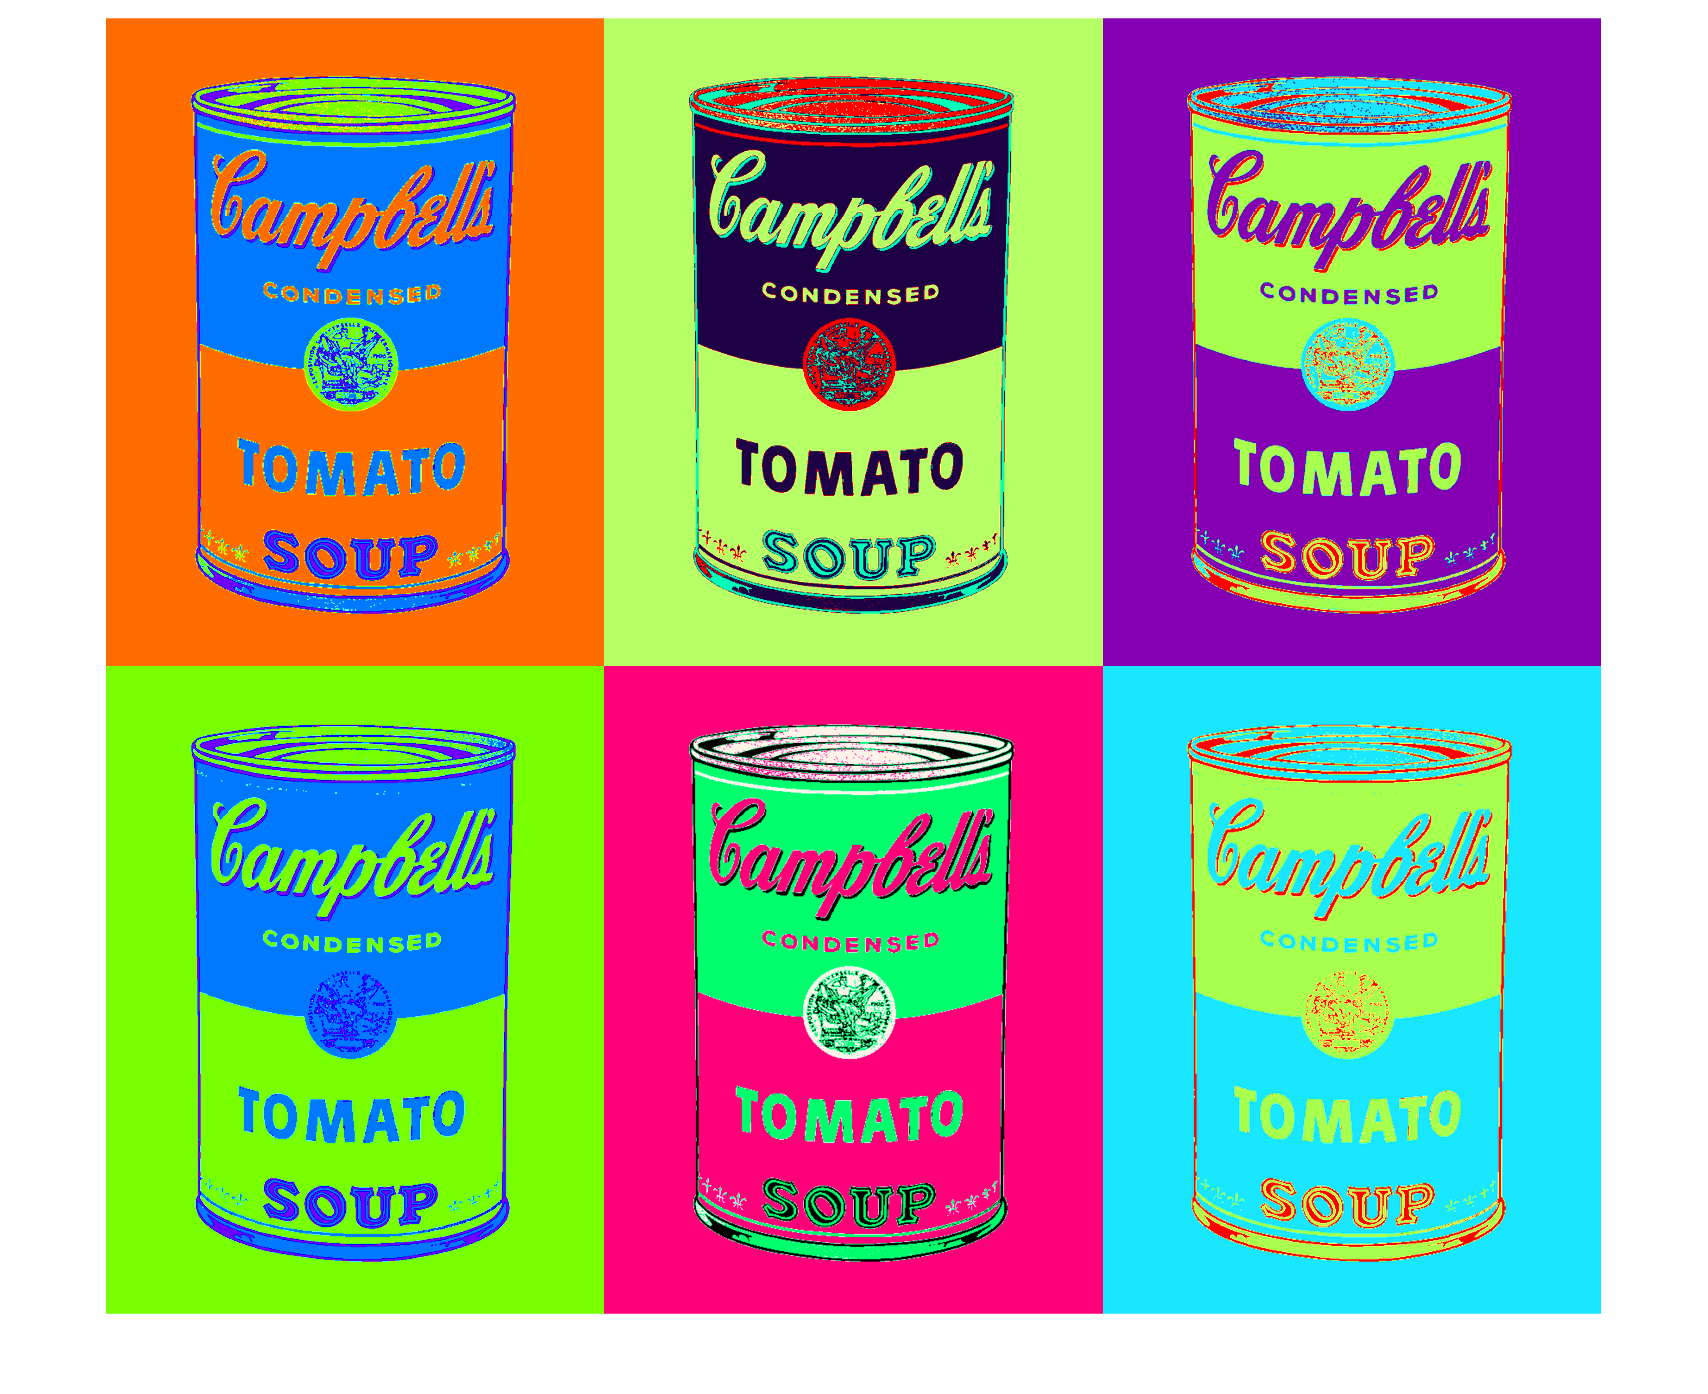

% convert from RGB to HSV
newImg = rgb2hsv(I);

% split into 3 channels
[h, s, v] = imsplit(newImg);

% add 0.1 to saturation
s = s + 0.1;

% add 0.08 to hue
h = h + 0.08;

% conactenate back to one image
hsvImg = cat(3, h, s, v);

% convert form HSV to RGB
rgbImg = hsv2rgb(hsvImg);

imshow(rgbImg)